# Introduction to differential protein expression analysis

The goal is to search for specific residues that could explain the differences in expression levels measured experimentally. 

## Retrieval of amino acid sequences

In this example we retrieve a list of PDB IDs of sequences similar to 5VGE (HLA-C: major histocompatibility complex, class I, C [human]) using the [Protein Data Bank](https://www.rcsb.org/)

pdbfolder = 'pdbFiles';
ids = fileread("list_ID.txt");

ids = preProcessID(ids)

Read 884 IDs


ids = 20×1 string array
    "6AMT"
    "4WU5"
    "3VCL"
    "5F9J"
    "7QPJ"
    "2NX5"
    "7N2O"
    "4L3C"
    "3GSQ"
    "5FA3"
    "3VFR"
    "5HHQ"
    "8ERX"
    "3RWH"
    "4EUP"
    "7S7E"
    "1E28"
    "4F7P"
    "3QEQ"
    "8GVG"


Create folder if it does not exist and download amino acid sequences

if ~exist(pdbfolder,'dir')
    mkdir(pdbfolder);
end
% arrayfun(@(filename) getpdb(filename,ToFile=fullfile(pdbfolder,filename+".pdb")),ids);
arrayfun(@(ID) getpdb(ID, ToFile=fullfile(pdbfolder,ID+".pdb")), ids);

              Header: [1×1 struct]
               Title: [2×60 char]
            Compound: [13×31 char]
              Source: [20×46 char]
            Keywords: 'MHC CLASS I, ANTIGEN PRESENTATION, IMMUNE SYSTEM'
      ExperimentData: 'X-RAY DIFFRACTION'
             Authors: 'M.ASA,D.MORITA,M.SUGITA'
        RevisionDate: [1×2 struct]
             Journal: [1×1 struct]
             Remark2: [1×1 struct]
             Remark3: [1×1 struct]
             Remark4: [2×59 char]
           Remark100: [3×59 char]
           Remark200: [49×59 char]
           Remark280: [7×59 char]
           Remark290: [24×59 char]
           Remark300: [6×59 char]
           Remark350: [20×59 char]
           Remark465: [62×59 char]
           Remark500: [26×59 char]
           Remark620: [25×59 char]
        DBReferences: [1×4 struct]
            Sequence: [1×6 struct]
           Heterogen: [1×52 struct]
       HeterogenName: [1×4 struct]
    HeterogenSynonym: [1×2 struct]
             Formula: [1×5 struct]
 

Read amino acid sequences from local files

seqs = arrayfun(@(ID) readSeqFromPDBFile(fullfile(pdbfolder,ID+".pdb")), ids, UniformOutput=false);

seqs = 20×1 string array
    "AGSHSMRYFSTSVSRPGRGEPRFIAVGYVDDTQFVRFDSDAASQRMEPRAPWIEQEGPEYWDEETGKVKAHSQTDRENLRIALRYYNQSEAGSHTLQMMFGCDVGSDGRFLRGYHQYAYDGKDYIALKEDLRSWTAADMAAQITKRKWEAAHVAEQQRAYLEGTCVDGLRRYLENGKETLQRTDPPKTHMTHHPISDHEATLRCWALGFYPAEITLTWQRDGEDQTQDTELVETRPAGDGTFQKWAAVVVPSGEEQRYTCHVQHEGLPKPLTLRWEP"
    "GSHSMRYFSTSVSRPGRGEPRFIAVGYVDDTQFVRFDSDAASQRMEPRAPWIEQEGPEYWDEETGKVKAHSQTDRENLRIALRYYNQSEAGSHTLQMMFGCDVGSDGRFLRGYHQYAYDGKDYIALKEDLRSWTAADMAAQITKRKWEAAHVAEQQRAYLEGTCVDGLRRYLENGKETLQRTDPPKTHMTHHPISDHEATLRCWALGFYPAEITLTWQRDGEDQTQDTELVETRPAGDGTFQKWAAVVVPSGEEQRYTCHVQHEGLPKPLTLRWEPSS"
    "GSHSMRYFFTSVSRPGRGEPRFIAVGYVDDTQFVRFDSDAASQRMEPRAPWIEQEGPEYWDGETRKVKAHSQTHRVDLGTLRGYYNQSEAGSHTVQRMYGCDVGSDWRFLRGYHQYAYDGKDYIALKEDLRSWTAADMAAQTTKHKWEAAHVAEQLRAYLEGTCVEWLRRYLENGKETLQRTDAPKTHMTHHAVSDHEATLRCWALSFYPAEITLTWQRDGEDQTQDTELVETRPAGDGTFQKWVAVVVPSGQEQRYTCHVQHEGLPKPLTLRWE"
    "MASGSHSMRYFFTSVSRPGRGEPRFIAVGYVDDTQFVRFDSDAASQRMEPRAPWIEQEGPEYWDQETRNVKAQSQTDRVDLGTLRGYYNQSEAGSHTIQIMYGCDVGSDGRFLRGYRQD

We produce dummy expression levels for the purpose of this example.

explevels = 2.^(-1 + 2*rand(log2(2), numel(ids),1))';

Data can saved in a dictionary or a table

dSeqs = dictionary(ids, seqs)


dSeqs =

  dictionary (string ⟼ string) with 20 entries:

    "7WT4" ⟼ "AGSHSMRYFSTSVSRPGRGEPRFIAVGYVDDTQFVRFDSDAASQRMEPRAPWIEQEGPEYWDEETGKVKAHSQTDRENLRIALRYYNQSEAGSHTLQMMFGCDVGSDGRFLRGYHQYAYDGKDYIALKEDLRSWTAADMAAQITKRKWEAAHVAEQQRAYLEGTCVDGLRRYLENGKETLQRTDPPKTHMTHHPISDHEATLRCWALGFYPAEITLTWQRDGEDQTQDTELVETRPAGDGTFQKWAAVVVPSGEEQRYTCHVQHEGLPKPLTLRWEP"
    "7JYW" ⟼ "GSHSMRYFSTSVSRPGRGEPRFIAVGYVDDTQFVRFDSDAASQRMEPRAPWIEQEGPEYWDEETGKVKAHSQTDRENLRIALRYYNQSEAGSHTLQMMFGCDVGSDGRFLRGYHQYAYDGKDYIALKEDLRSWTAADMAAQITKRKWEAAHVAEQQRAYLEGTCVDGLRRYLENGKETLQRTDPPKTHMTHHPISDHEATLRCWALGFYPAEITLTWQRDGEDQTQDTELVETRPAGDGTFQKWAAVVVPSGEEQRYTCHVQHEGLPKPLTLRWEPSS"
    "3FT3" ⟼ "GSHSMRYFFTSVSRPGRGEPRFIAVGYVDDTQFVRFDSDAASQRMEPRAPWIEQEGPEYWDGETRKVKAHSQTHRVDLGTLRGYYNQSEAGSHTVQRMYGCDVGSDWRFLRGYHQYAYDGKDYIALKEDLRSWTAADMAAQTTKHKWEAAHVAEQLRAYLEGTCVEWLRRYLENGKETLQRTDAPKTHMTHHAVSDHEATLRCWALSFYPAEITLTWQRDGEDQTQDTELVETRPAGDG

entries(dSeqs)

ans = 20×2 table
     Key                                                                                                                                                          Value                                                                                                                                                     
    ______    ______________________________________________________________________________________________________________________________________________________________________________________________________________________________________________________________________________________________________________

    "7WT4"    "AGSHSMRYFSTSVSRPGRGEPRFIAVGYVDDTQFVRFDSDAASQRMEPRAPWIEQEGPEYWDEETGKVKAHSQTDRENLRIALRYYNQSEAGSHTLQMMFGCDVGSDGRFLRGYHQYAYDGKDYIALKEDLRSWTAADMAAQITKRKWEAAHVAEQQRAYLEGTCVDGLRRYLENGKETLQRTDPPKTHMTHHPISDHEATLRCWALGFYPAEITLTWQRDGEDQTQDTELVETRPAGDGTFQKWAAVVVPSGEEQRYTCHVQHE

tSeqs = table(seqs,log2(explevels),VariableNames=["Sequence","log2(ExpLevel)"],RowNames=ids)

tSeqs = 20×2 table
                                                                                                                                                               Sequence                                                                                                                                                       log2(ExpLevel)
            ______________________________________________________________________________________________________________________________________________________________________________________________________________________________________________________________________________________________________________    ______________

    7WT4    "AGSHSMRYFSTSVSRPGRGEPRFIAVGYVDDTQFVRFDSDAASQRMEPRAPWIEQEGPEYWDEETGKVKAHSQTDRENLRIALRYYNQSEAGSHTLQMMFGCDVGSDGRFLRGYHQYAYDGKDYIALKEDLRSWTAADMAAQITKRKWEAAHVAEQQRAYLEGTCVDGLRRYLENGKETLQRTDPPKTHMTHHPISDHEATLRCWALGFYPAEITL

To retrieve a specific sequence, we can use these notations:

ID = ids(8);
dSeqs(ID)

ans = "GSHSMRYFFTSVSRPGRGEPRFIAVGYVDDTQFVRFDSDAASQRMEPRAPWIEQEGPEYWDGETRKVKAHSQTHRVDLGTLRGYYNQSEAGSHTVQRMYGCDVGSDWRFLRGYHQYAYDGKDYIALKEDLRSWTAADMAAQTTKHKWETAHEAEQWRAYLEGTCVEWLRRYLENGKETLQRTDAPKTHMTHHAVSDHEATLRCWALSFYPAEITLTWQRDGEDQTQDTELVETRPAGDGTFQKWAAVVVPSGQEQRYTCHVQHEGLPKPLTLRWE"

or

tSeqs.Sequence(ID)

ans = "GSHSMRYFFTSVSRPGRGEPRFIAVGYVDDTQFVRFDSDAASQRMEPRAPWIEQEGPEYWDGETRKVKAHSQTHRVDLGTLRGYYNQSEAGSHTVQRMYGCDVGSDWRFLRGYHQYAYDGKDYIALKEDLRSWTAADMAAQTTKHKWETAHEAEQWRAYLEGTCVEWLRRYLENGKETLQRTDAPKTHMTHHAVSDHEATLRCWALSFYPAEITLTWQRDGEDQTQDTELVETRPAGDGTFQKWAAVVVPSGQEQRYTCHVQHEGLPKPLTLRWE"

## Multiple sequence alignment and visualization

Perform progressive multiple sequence alignment. This will allow you to identify conserved and variable regions across the sequences.

Pairwise distances between sequences are computed after pairwise alignment with the Gonnet scoring matrix and then by counting the proportion of sites at which each pair of sequences are different (ignoring gaps). The guide tree is calculated by the neighbor-joining method assuming equal variance and independence of evolutionary distance estimates.

seqsMultiAligned = multialign(seqs,TerminalGapAdjust=false)

seqsMultiAligned = 20×365 char array
    '-----------------------AGSHSMRYFSTSVSRPGRGEPRFIAVGYVDDTQFVRFDSDAASQRMEPRAPWIEQEGPEYWDEETGKVKAHSQTDRENLRIALRYYNQSEAGSHTLQMMFGCDVGSDGRFLRGYHQYAYDGKDYIALKEDLRSWTAADMAAQITKRKWEAAHVAEQQRAYLEGTCVDGLRRYLENGKETLQRTDPPKTHMTHHPISDHEATLRCWALGFYPAEITLTWQRDGEDQTQDTELVETRPAGDGTFQKWAAVVVPSGEEQRYTCHVQHEGLPKPLTLRWEP-----------------------------------------------------------------'
    '------------------------GSHSMRYFSTSVSRPGRGEPRFIAVGYVDDTQFVRFDSDAASQRMEPRAPWIEQEGPEYWDEETGKVKAHSQTDRENLRIALRYYNQSEAGSHTLQMMFGCDVGSDGRFLRGYHQYAYDGKDYIALKEDLRSWTAADMAAQITKRKWEAAHVAEQQRAYLEGTCVDGLRRYLENGKETLQRTDPPKTHMTHHPISDHEATLRCWALGFYPAEITLTWQRDGEDQTQDTELVETRPAGDGTFQKWAAVVVPSGEEQRYTCHVQHEGLPKPLTLRWEPSS---------------------------------------------------------------'
    '------------------------GSHSMRYFFTSVSRPGRGEPRFIAVGYVDDTQFVRFDSDAASQRMEPRAPWIEQEGPEYWDGETRKVKAHSQTHRVDLGTLRGYYNQSEAGSHTVQRMYGCDVGSDWRFLRGYHQYAYDGKDYIALKEDLRSWTAADMAAQTTKHKWEAAHVAEQLRAYLEGTCVEWLRRYLENGKETLQRTDAPKTHMT

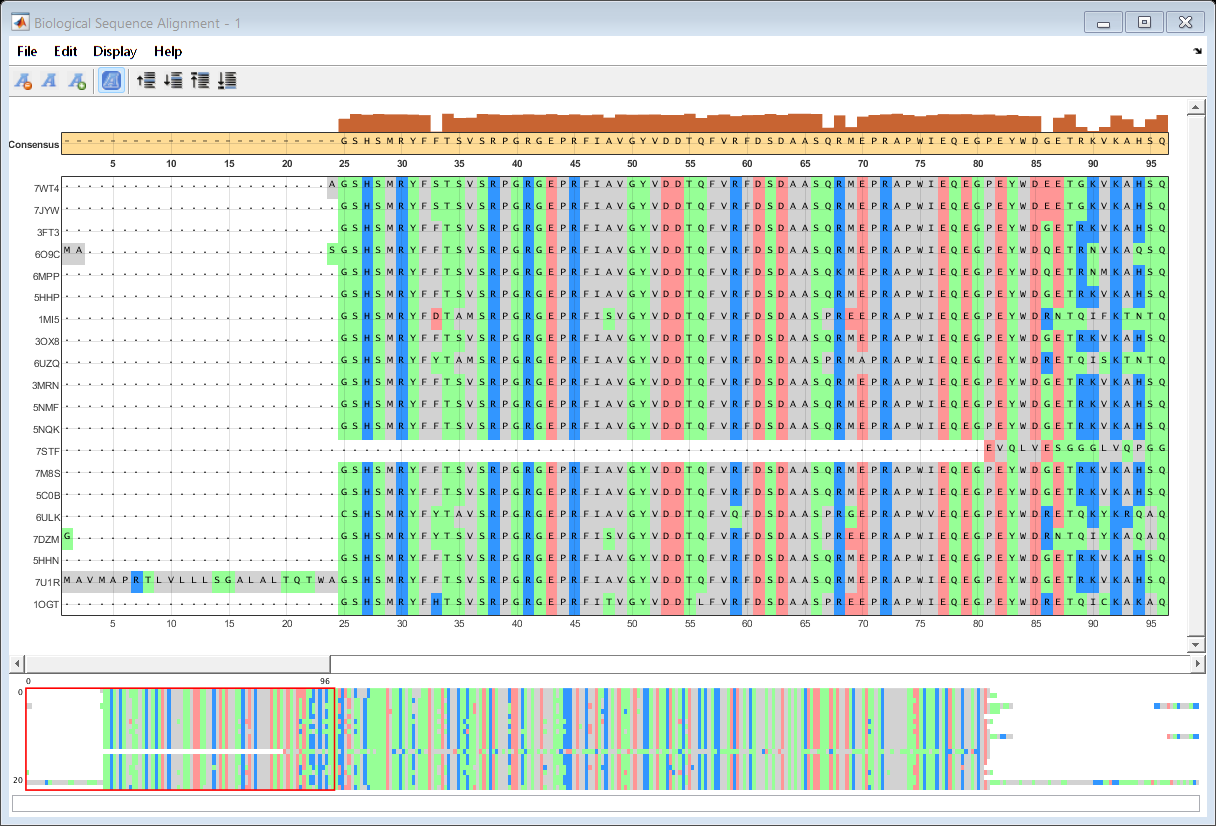

seqalignviewer(seqsMultiAligned, SeqHeaders=ids, Alphabet='AA')

Compute consensus sequence and conservation scores

[CSeq, Score] = seqconsensus(seqsMultiAligned, Alphabet='AA', Gaps='all')

CSeq = '------------------------GSHSMRYFFTSVSRPGRGEPRFIAVGYVDDTQFVRFDSDAASQRMEPRAPWIEQEGPEYWDGETRKVKAHSQTHRVDLGTLRGYYNQSEAGSHTVQRMYGCDVGSDWRFLRGYHQYAYDGKDYIALKEDLRSWTAADMAAQTTKHKWEAAHVAEQLRAYLEGTCVEWLRRYLENGKETLQRTDPPKTHMTHHPVSDHEATLRCWALGFYPAEITLTWQRDGEDQTQDTELVETRPAGDGTFQKWAAVVVPSGQEQRYTCHVQHEGLPKPLTLRWEP-----------------------------------------------------------------'

Score =     3.4431    2.0986    1.3827    1.3410    1.1076    1.5770    1.3366    1.0923    1.3883    1.3827    1.3883    1.3883    1.3883    1.1753    1.4869    1.1076    1.3883    1.1076    1.3883    1.0923    1.2917    1.0923    2.0966    2.9885    3.0824    1.1753    1.4886    1.1753    1.3410    1.3366    1.4544    1.6260    8.1918    1.0923    2.7217    2.7109    1.1753    1.3366    1.5770    1.4869    1.3366    1.4869    1.2728    1.5770    1.3366    1.6260    1.4593    2.6150    1.3827    1.4869


## Residue Analysis

Analyze the residues in the variable regions. Look for specific residues that could potentially explain the difference in expression levels. 

## Phylogenetic analysis

Perform phylogenetic analysis to understand the evolutionary relationships between your protein sequences. This could help identify clusters of sequences with similar expression levels.

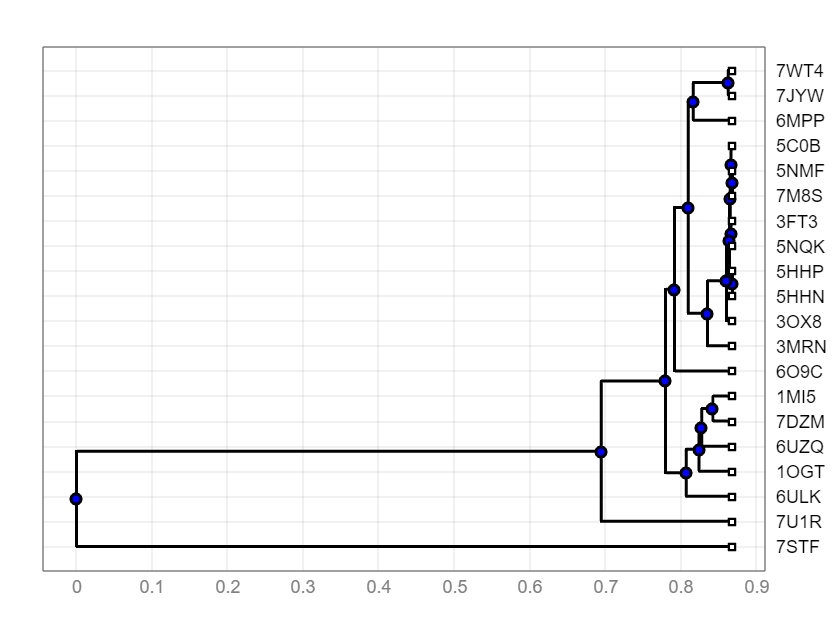

distances = seqpdist(seqs, Method='jukes-cantor');
phylotree = seqlinkage(distances,'average',ids);
plot(phylotree)

% view(phylotree)

## Protein Structure Prediction

Use a protein structure prediction tool to predict the 3D structure of your proteins and help identify the location of specific residues and their potential impact on protein function and expression.

Here, we will use the [AlphaFold Protein Structure Database from EBI](https://alphafold.ebi.ac.uk/api-docs). It takes a UniProt Accession in its request. So, we will start by converting the PDB IDs into UniProt IDs using the REST API provided by [UniProt.org](https://rest.uniprot.org/idmapping/).

selectedIDs = ["5VGE",... % HLA-C*07:02
               "5VGD"];   % HLA-C*0501
UniPROTIDs = convertPDB2UniProt(selectedIDs)

UniPROTIDs = 3×1 string array
    "P10321"
    "P61769"
    "P68431"


Now that we have the IDs, we can send a prediction request to the alphafold database and save the corresponding PDB files.

predStruct = predictStructureAlphafoldEBI(UniPROTIDs)

predStruct = struct with fields:
    Status: "success"
     Files: [3×1 string]


predStruct.Files

ans = 3×1 string array
    "C:\Users\jhuard\Bioinfo\Protein_expression_structural_analysis\P10321.pdb"
    "C:\Users\jhuard\Bioinfo\Protein_expression_structural_analysis\P61769.pdb"
    "C:\Users\jhuard\Bioinfo\Protein_expression_structural_analysis\P68431.pdb"


## Protein structure visualization

We can use the generated PDB files and visualize the protein structures.

s5VGE = pdbread(predStruct.Files(1)) %#ok<NASGU>

s5VGE = struct with fields:
          Header: [1×1 struct]
           Title: [2×60 char]
        Compound: [3×59 char]
          Source: [3×34 char]
         Remark1: [1×1 struct]
    DBReferences: [1×1 struct]
        Sequence: [1×1 struct]
          Cryst1: [1×1 struct]
         OriginX: [1×3 struct]
           Scale: [1×3 struct]
           Model: [1×1 struct]


Alternatively, we can grab the PDB file from the PDB server if available.

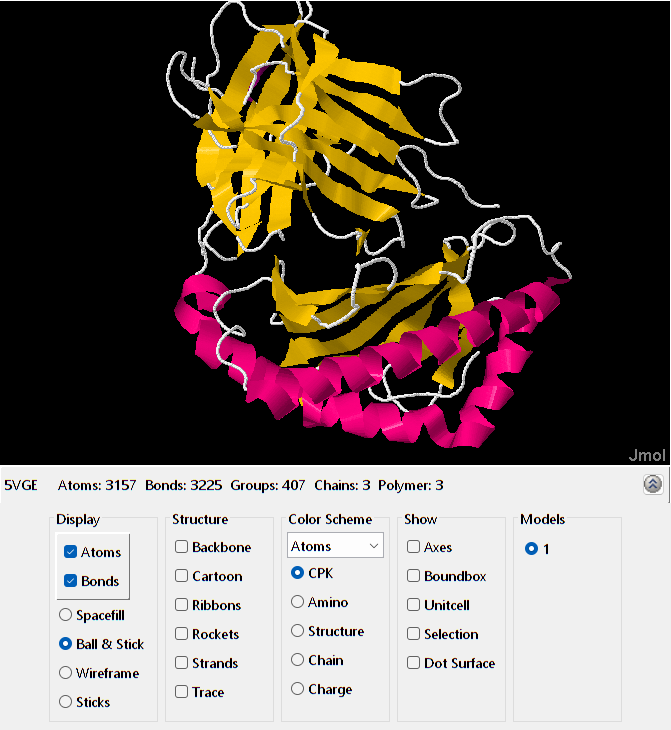

s5VGE = getpdb('5VGE'); 

h = molviewer(s5VGE);

evalrasmolscript(h, ['spacefill off; wireframe off; ' ...
                      'restrict protein; cartoon on; color structure; ' ...
                      'center selected;']);

Let's now superpose both structures.

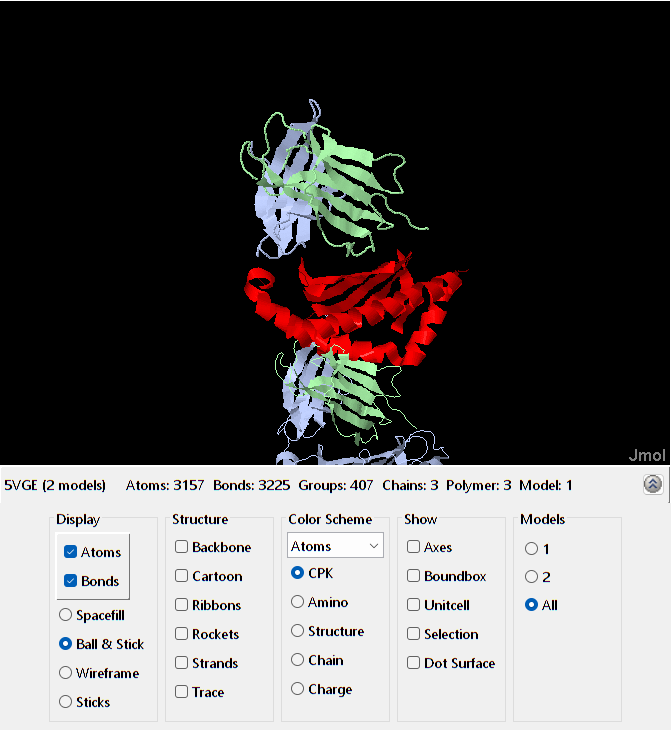

if isvalid(h), close(h); end

s5VGD = getpdb('5VGD');

[Dist, RMSD, Transf, PBD2TX] = pdbsuperpose(s5VGE, s5VGD, Display=true);


h3 = findobj('Tag', 'BioinfoMolviewer'); 
evalrasmolscript(h3, 'select all; center selected; zoom 200;');

evalrasmolscript(h3, ['select all; cartoons off; ' ...
                      'select model = 1; strands on; color red; ' ...% 5VGE
                      'select model = 2; strands on; color blue;']); % 5VGD